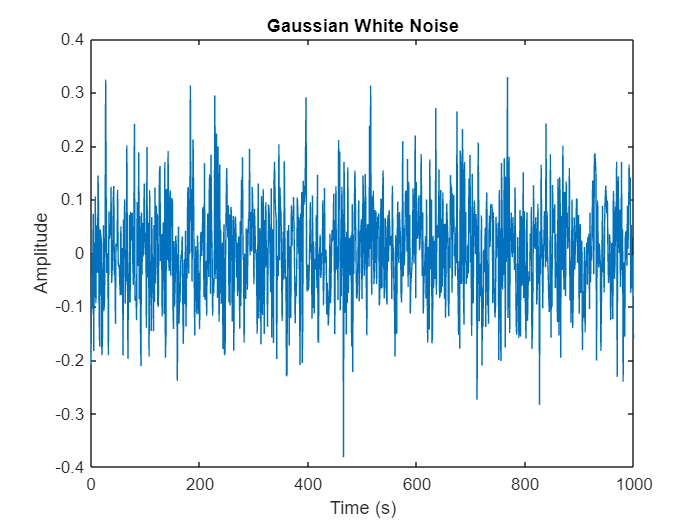

N = 1000;
stdev = 0.1;
noise = init_noise(N, stdev);

Ts = 1;
time = Ts * (0:N-1);

plot(time, noise);

title('Gaussian White Noise');
xlabel('Time (s)');
ylabel('Amplitude');

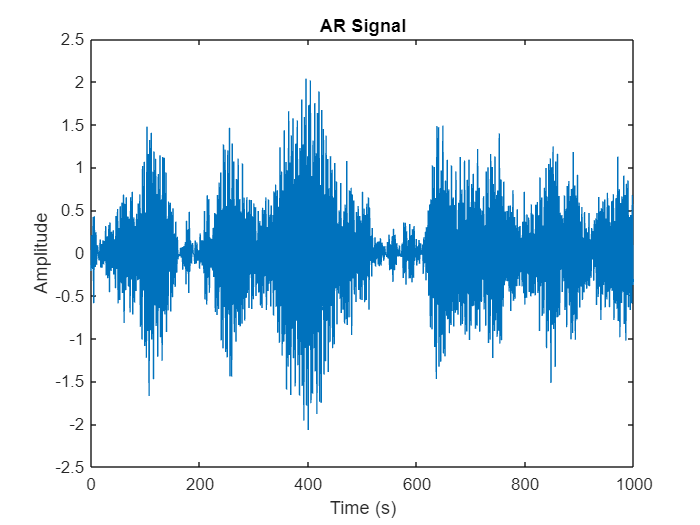

b = 1;
a = [1, 1.4, 0.981];
signal = init_signal(noise, a, b);

plot(time, signal);
title('AR Signal');
xlabel('Time (s)');
ylabel('Amplitude');

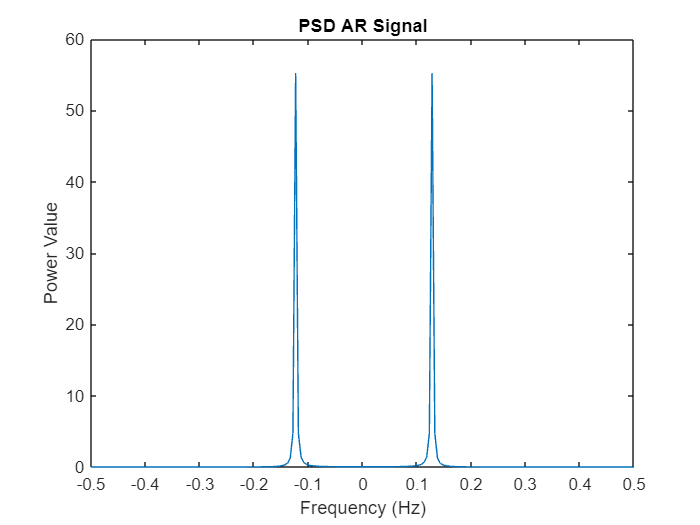

fs = 1/Ts;
N_freqs = 200;

gain = gain_filter(a, b, N_freqs, fs);
psd_signal = gain.^2 * stdev^2;

freqs = linspace(-fs/2, fs/2, N_freqs);
freqs_for_graph = linspace(-fs/2, fs/2, 11);
plot(freqs, psd_signal);
title('PSD AR Signal');
xlabel('Frequency (Hz)');
xticks(freqs_for_graph);
ylabel('Power Value');

p = 2;
[coeffs, ~] = yule_walker(signal, p);

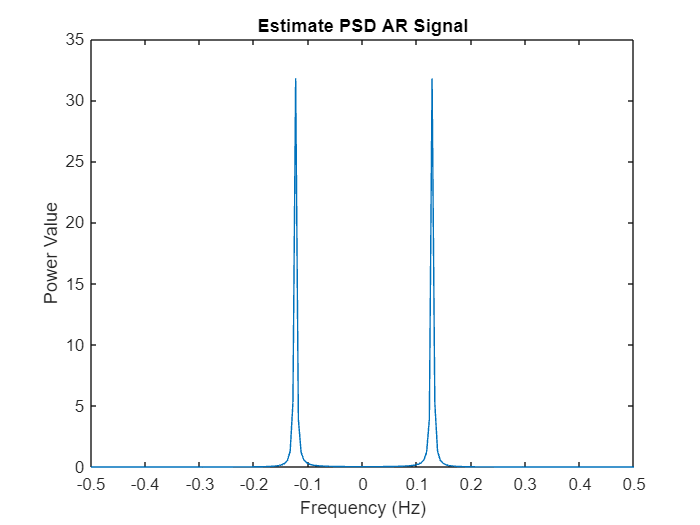

a_estim = [1; -coeffs]'; % because at the beginning, we had sum for i=0 to p of a(i) * X(n-i) = B(n); i.e. X_pred(n) - sum for i=1 to p of coeff_i * X(n-i) = B(n)
gain_estim = gain_filter(a_estim, b, N_freqs, fs);
psd_signal_estim = gain_estim.^2 * stdev^2 ;

freqs = linspace(-fs/2, fs/2, N_freqs);
freqs_for_graph = linspace(-fs/2, fs/2, 11);
plot(freqs, psd_signal_estim);
title('Estimate PSD AR Signal');
xlabel('Frequency (Hz)');
xticks(freqs_for_graph);
ylabel('Power Value');

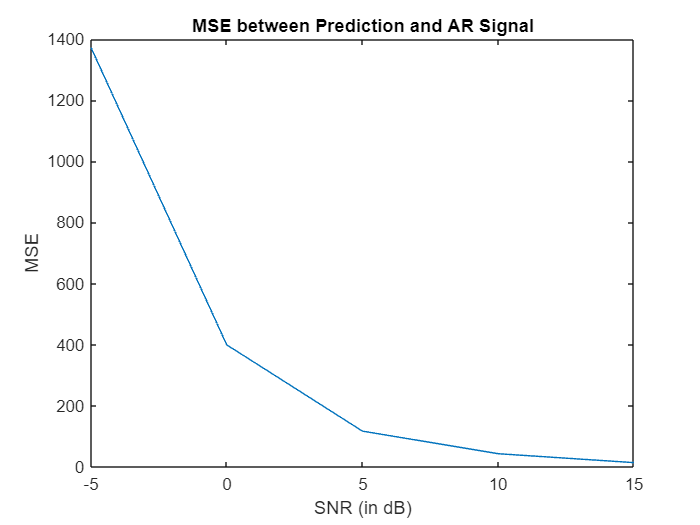

array_SNR = [-5, 0, 5, 10, 15];
array_mse = zeros(1, length(array_SNR));

for i = 1:length(array_SNR)

    noisy_signal = add_noise(signal, array_SNR(i));
    [coeffs_i, mse_i] = yule_walker(noisy_signal, p);
    array_mse(i) = mse_i;
end
plot(array_SNR, array_mse);
title('MSE between Prediction and AR Signal');
xlabel('SNR (in dB)');
ylabel('MSE');

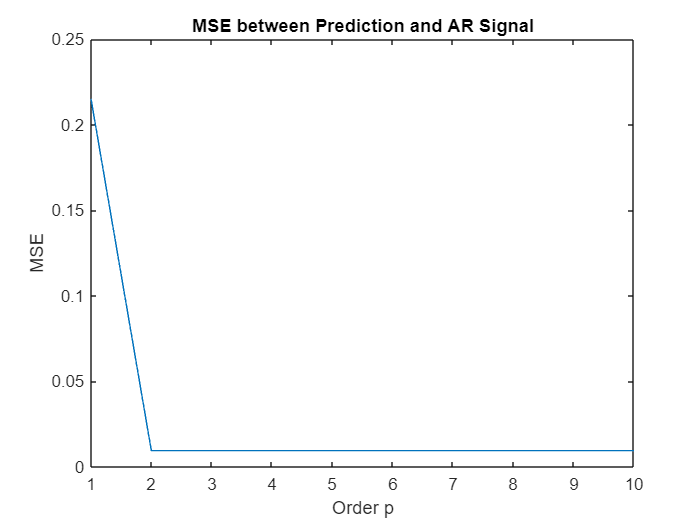

array_p = 1:10;
array_mse_bis = zeros(1, length(array_p));

for i = 1:length(array_p)

    [coeffs_i, mse_i] = yule_walker(signal, array_p(i));
    array_mse_bis(i) = mse_i;
end
plot(array_p, array_mse_bis);
title('MSE between Prediction and AR Signal');
xlabel('Order p');
ylabel('MSE');

[~, ind_mse] = min(array_mse_bis);
fprintf('Best order p = %d', array_p(ind_mse));

Best order p = 9

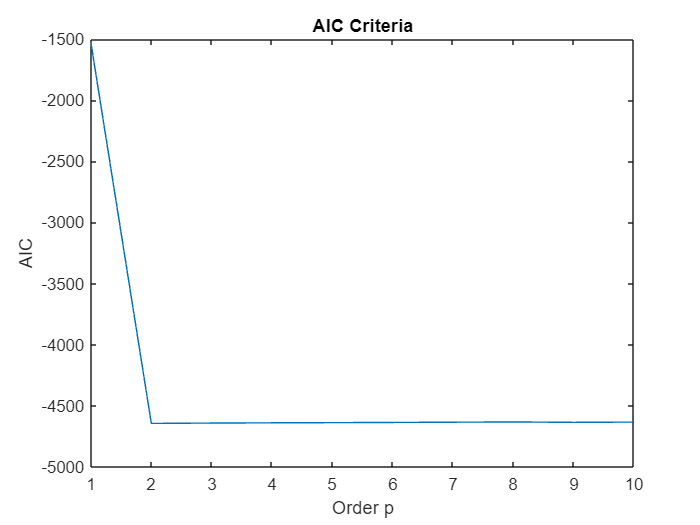

array_aic = zeros(1, length(array_p));

for i = 1:length(array_p)

    aic_i = signal_aic(signal, array_p(i));
    array_aic(i) = aic_i;
end
plot(array_p, array_aic);
title('AIC Criteria');
xlabel('Order p');
ylabel('AIC');

[~, ind_aic] = min(array_aic);
fprintf('Best order p = %d', array_p(ind_aic));

Best order p = 2

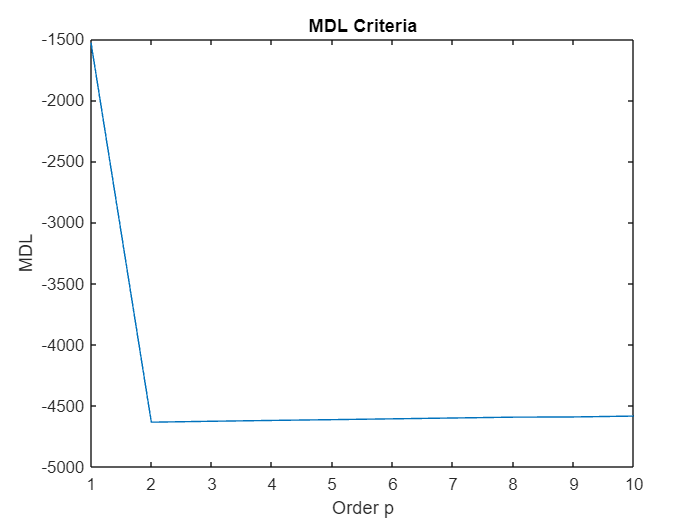

array_mdl = zeros(1, length(array_p));

for i = 1:length(array_p)

    mdl_i = signal_mdl(signal, array_p(i));
    array_mdl(i) = mdl_i;
end
plot(array_p, array_mdl);
title('MDL Criteria');
xlabel('Order p');
ylabel('MDL');

[~, ind_mdl] = min(array_mdl);
fprintf('Best order p = %d', array_p(ind_mdl));

Best order p = 2

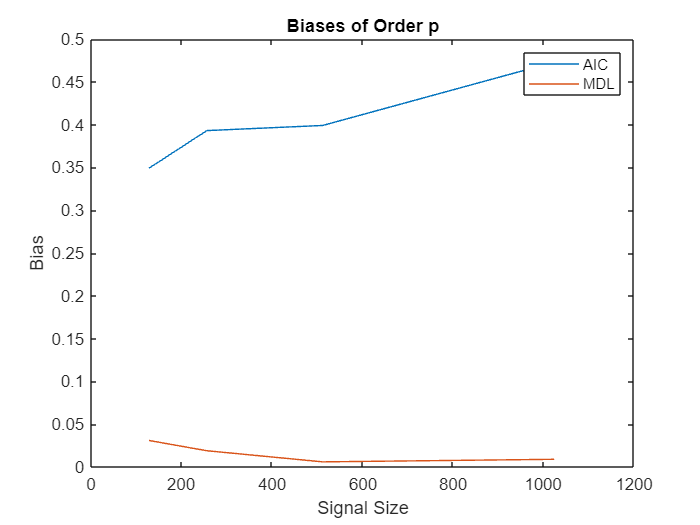

signal_sizes = [128, 256, 512, 1024];
N_reals = 1000;

values_p_aic = zeros(length(signal_sizes), N_reals);
values_p_mdl = zeros(length(signal_sizes), N_reals);

for i = 1:length(signal_sizes)

    for real = 1:N_reals
    
        noise_real = init_noise(signal_sizes(i), stdev);
        signal_real = init_signal(noise_real, a, b);

        array_aic_real = zeros(1, length(array_p));
        array_mdl_real = zeros(1, length(array_p));
    
        for j = 1:length(array_p)
        
            aic_j = signal_aic(signal_real, array_p(j));
            array_aic_real(j) = aic_j;

            mdl_j = signal_mdl(signal_real, array_p(j));
            array_mdl_real(j) = mdl_j;
        end
    
        [~, ind_aic_real] = min(array_aic_real);
        values_p_aic(i, real) = array_p(ind_aic_real);

        [~, ind_mdl_real] = min(array_mdl_real);
        values_p_mdl(i, real) = array_p(ind_mdl_real);
    end
end

biases_aic = mean(values_p_aic, 2) - p;
biases_mdl = mean(values_p_mdl, 2) - p;

stdevs_aic = std(values_p_aic, 0, 2);
stdevs_mdl = std(values_p_mdl, 0, 2);

plot(signal_sizes, biases_aic);
hold on;
plot(signal_sizes, biases_mdl);
hold off;
legend("AIC", "MDL");
title('Biases of Order p');
xlabel('Signal Size');
ylabel('Bias');

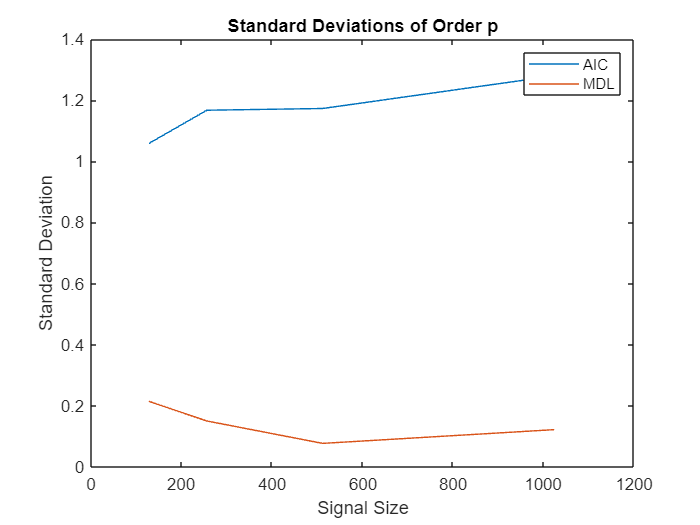


plot(signal_sizes, stdevs_aic);
hold on;
plot(signal_sizes, stdevs_mdl);
hold off;
legend("AIC", "MDL");
title('Standard Deviations of Order p');
xlabel('Signal Size');
ylabel('Standard Deviation');

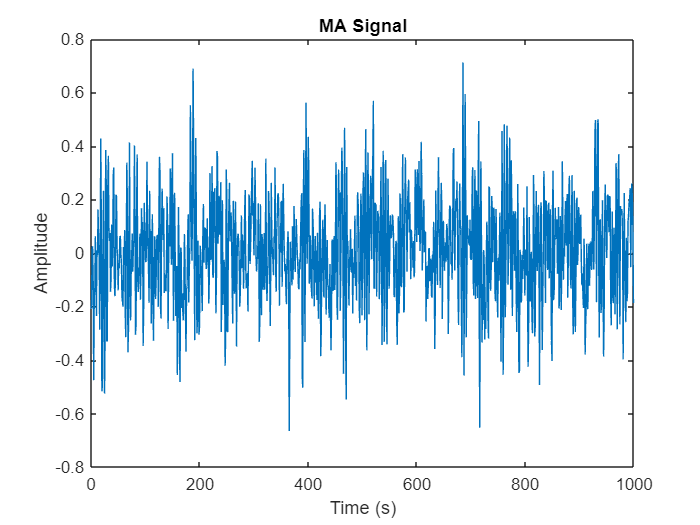

b2 = [1, 0.5, -0.3, -0.5, 0.8, 1.4];
a2 = 1;
signal2 = init_signal(noise, a2, b2);

plot(time, signal2);
title('MA Signal');
xlabel('Time (s)');
ylabel('Amplitude');

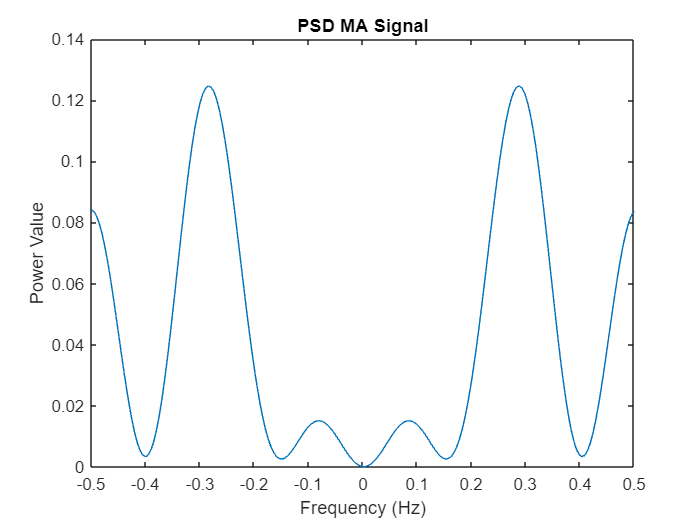

gain2 = gain_filter(a2, b2, N_freqs, fs);
psd_signal2 = gain2.^2 * stdev^2;

plot(freqs, psd_signal2);
title('PSD MA Signal');
xlabel('Frequency (Hz)');
xticks(freqs_for_graph);
ylabel('Power Value');

array_mdl2 = zeros(1, length(array_p));

for i = 1:length(array_p)

    mdl_i = signal_mdl(signal2, array_p(i));
    array_mdl2(i) = mdl_i;
end

[~, ind_mdl2] = min(array_mdl2);
fprintf('Best order p = %d', array_p(ind_mdl2));

Best order p = 10

p2 = array_p(ind_mdl2);
[coeffs2, ~] = yule_walker(signal2, p2);

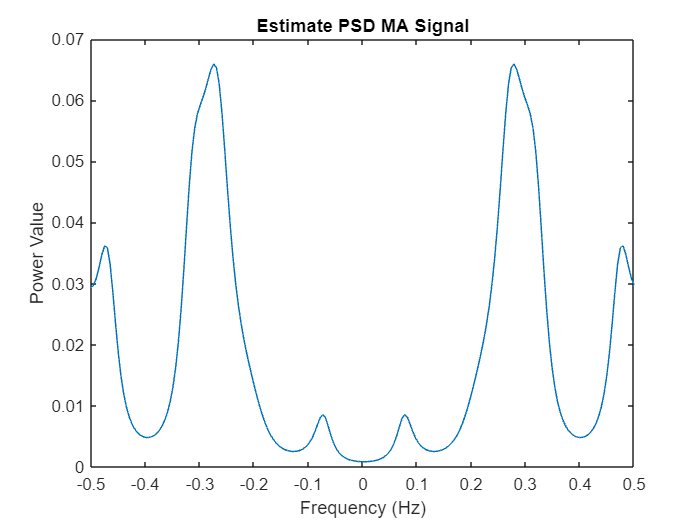

a_estim2 = [1; -coeffs2]'; % because at the beginning, we had sum for i=0 to p of a(i) * X(n-i) = B(n); i.e. X_pred(n) - sum for i=1 to p of coeff_i * X(n-i) = B(n)
gain_estim2 = gain_filter(a_estim2, b, N_freqs, fs);
psd_signal_estim2 = gain_estim2.^2 * stdev^2 ;

freqs = linspace(-fs/2, fs/2, N_freqs);
freqs_for_graph = linspace(-fs/2, fs/2, 11);
plot(freqs, psd_signal_estim2);
title('Estimate PSD MA Signal');
xlabel('Frequency (Hz)');
xticks(freqs_for_graph);
ylabel('Power Value');

frequency = 1;
amplitude = 0.5;
signal3 = amplitude * sin(2*pi*frequency*time);

array_mdl3 = zeros(1, length(array_p));

for i = 1:length(array_p)

    mdl_i = signal_mdl(signal3, array_p(i));
    array_mdl3(i) = mdl_i;
end

[~, ind_mdl3] = min(array_mdl3);
fprintf('Best order p = %d', array_p(ind_mdl3));

Best order p = 7

p3 = array_p(ind_mdl3);
[coeffs3, ~] = yule_walker(signal3, p3);

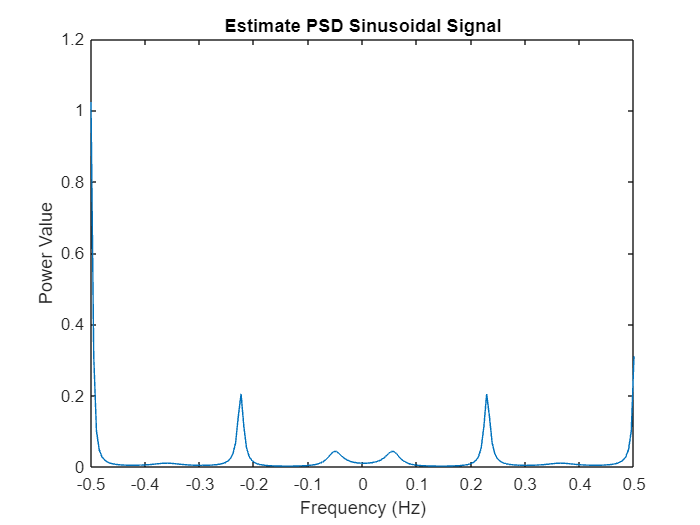

a_estim3 = [1; -coeffs3]'; % because at the beginning, we had sum for i=0 to p of a(i) * X(n-i) = B(n); i.e. X_pred(n) - sum for i=1 to p of coeff_i * X(n-i) = B(n)
gain_estim3 = gain_filter(a_estim3, b, N_freqs, fs);
psd_signal_estim3 = gain_estim3.^2 * stdev^2 ;

freqs = linspace(-fs/2, fs/2, N_freqs);
freqs_for_graph = linspace(-fs/2, fs/2, 11);
plot(freqs, psd_signal_estim3);
title('Estimate PSD Sinusoidal Signal');
xlabel('Frequency (Hz)');
xticks(freqs_for_graph);
ylabel('Power Value');

p = 2;
[coeffs_lev, mse_lev] = levinson(signal, p);